filePath1 = "/Users/elizabeth 1/Desktop/Wu Lab/6. clonogenic assay by EB copy/subimages retaken/"; %specify folder with image you want to analyze
cd(filePath1);
fileList = dir(fullfile(filePath1, '*.jpeg'));  % List all PNG files (modify the extension as needed)

tableName = "clonogenic"+'.xls'; %excel file where you want to store analysis stats
filePath2 = '/Users/elizabeth 1/Desktop/Wu Lab/6. clonogenic assay by EB copy/subimages retaken/results/' %folder for analysis results

filePath2 = '/Users/elizabeth 1/Desktop/Wu Lab/6. clonogenic assay by EB copy/subimages retaken/results/'

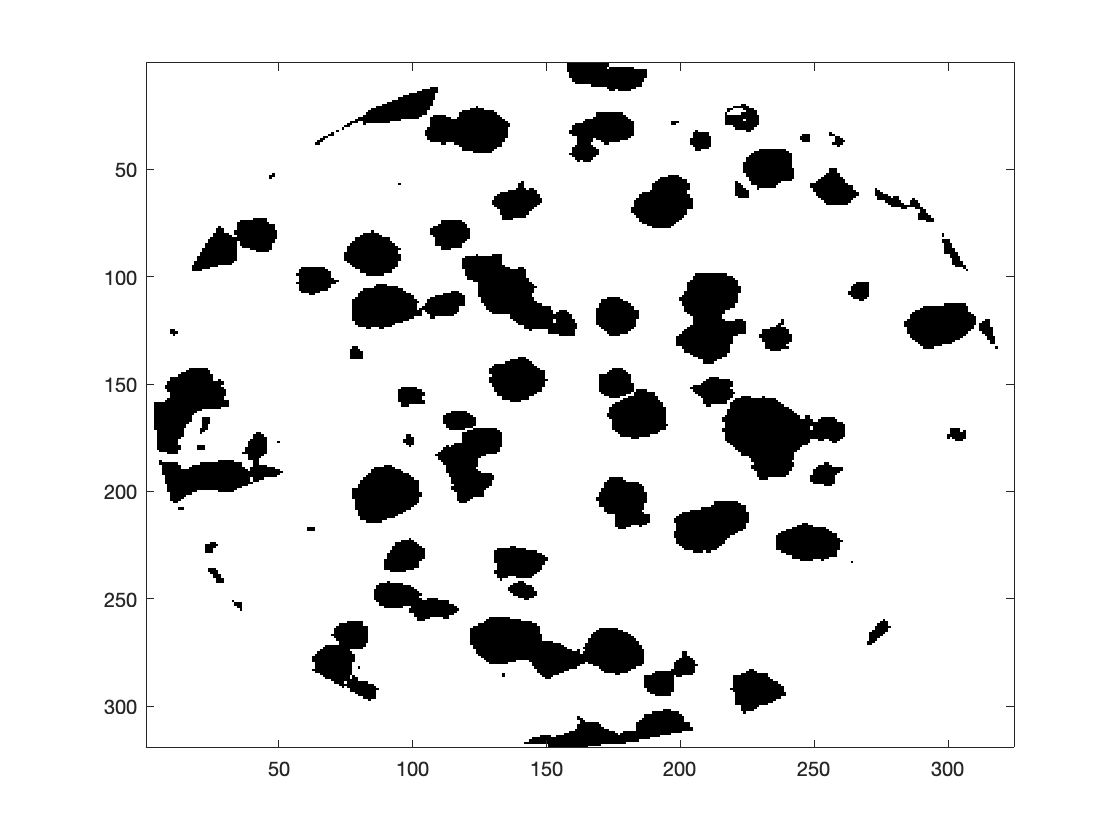

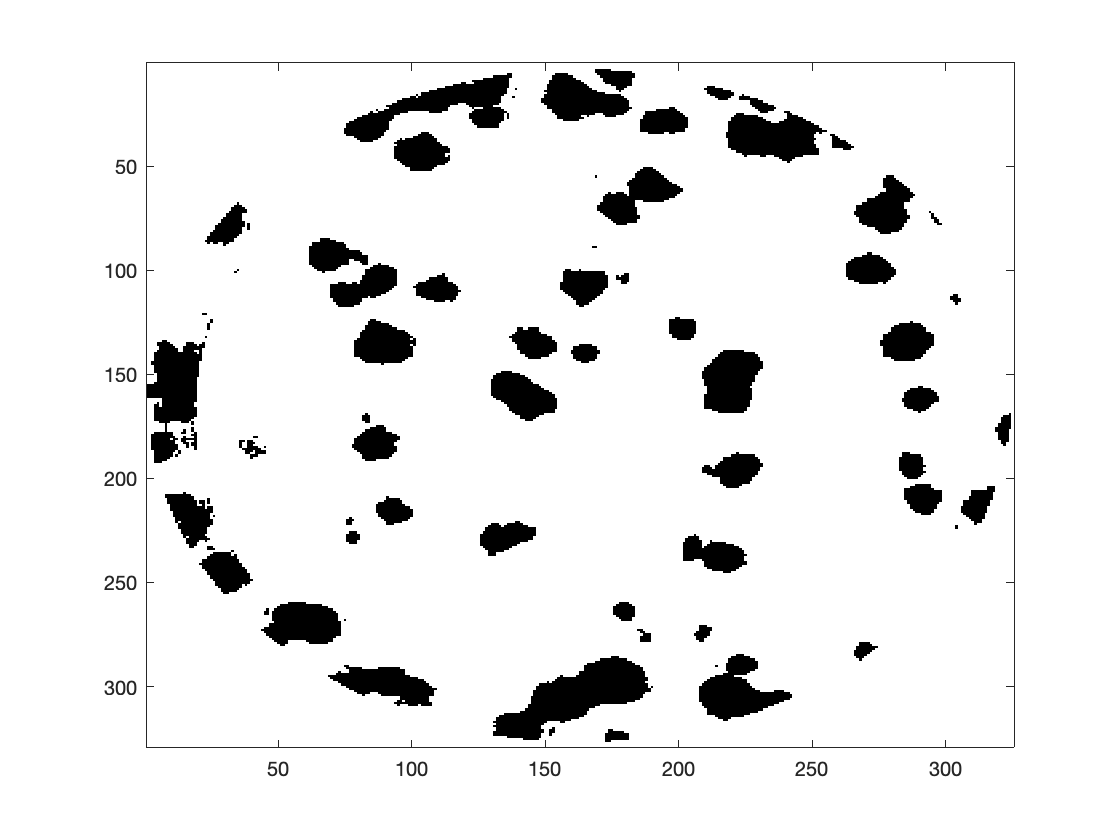

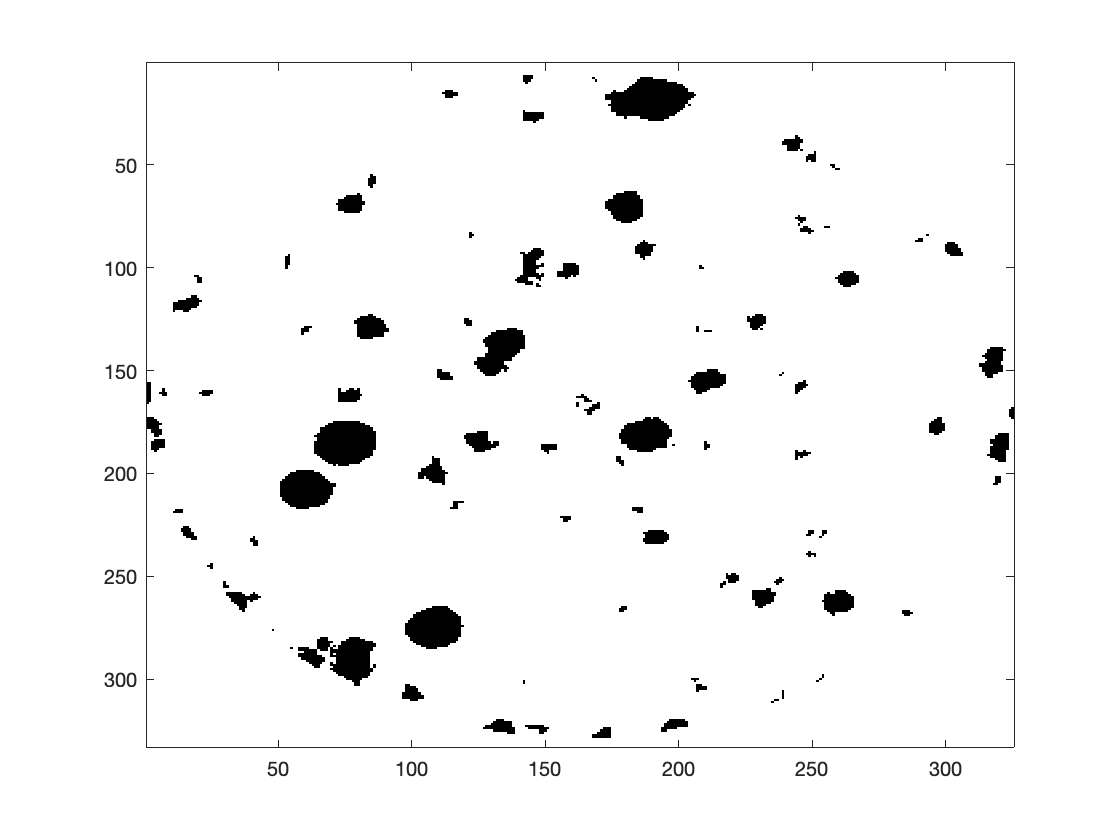

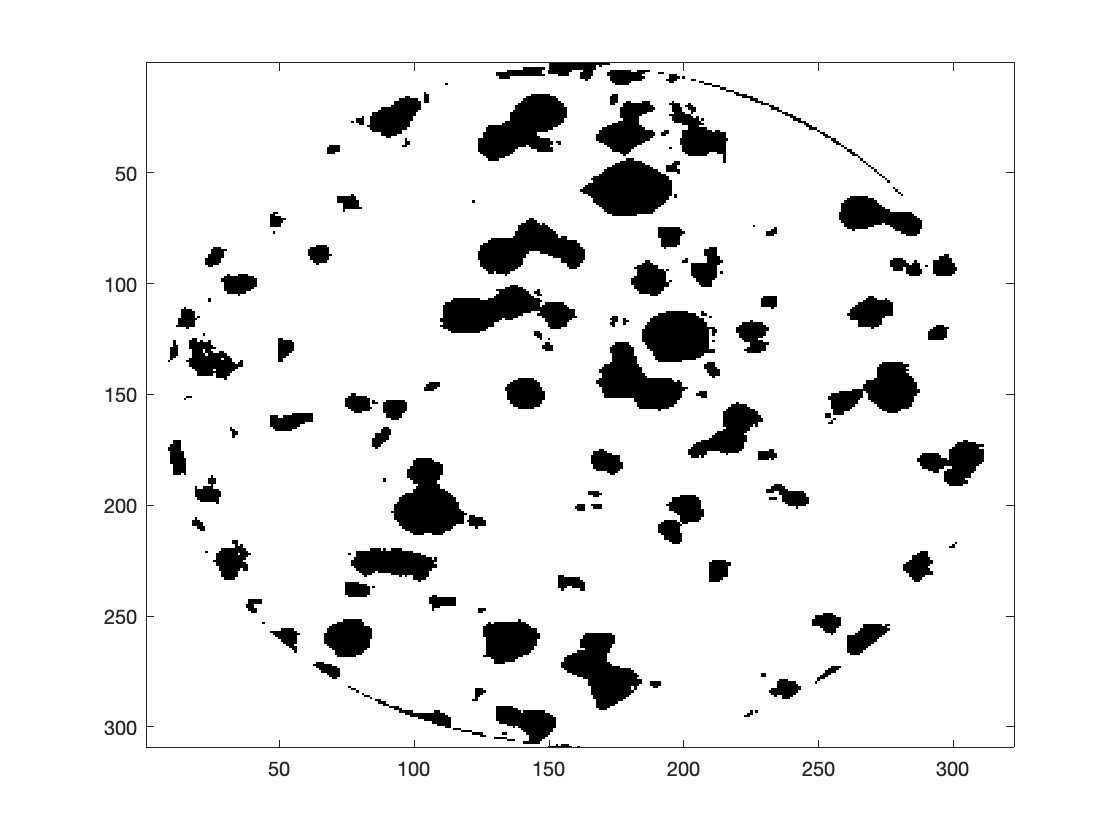


% Extract the filenames from the structure
filenames = {fileList.name}';
%allow user to use slider to iterate through images in the specified folder
%(don't have to type in image neame each time)
for i = 1:length(filenames)
    cd (filePath1);
    imgTitle = string(filenames(i));
    [analysisStats,C] = clonogenicAssay(imgTitle, filePath2, tableName, 90);
end



fprintf('This table is stored as %s in %s:', tableName, filePath2)

This table is stored as clonogenic.xls in /Users/elizabeth 1/Desktop/Wu Lab/6. clonogenic assay by EB copy/subimages retaken/results/:

analysisStats

analysisStats = 76×2 table
             PhotoName              colonies
    ____________________________    ________

    "7860_Atorva_1.25+VHLa.jpeg"      147   
    "7860_Atorva_1.25+VHLb.jpeg"      131   
    "7860_Atorva_1.25c.jpeg"          127   
    "7860_Atorva_1.25d.jpeg"          149   
    "7860_Atorva_10+VHLa.jpeg"         72   
    "7860_Atorva_10+VHLb.jpeg"         78   
    "7860_Atorva_10c.jpeg"             73   
    "7860_Atorva_10d.jpeg"             59   
    "7860_Atorva_2.5+VHLa.jpeg"       128   
    "7860_Atorva_2.5+VHLb.jpeg"       123   
    "7860_Atorva_2.5c.jpeg"           122   
    "7860_Atorva_2.5d.jpeg"           110   
    "7860_Atorva_5+VHLa.jpeg"         140   
    "7860_Atorva_5+VHLb.jpeg"         128   
    "7860_Atorva_5c.jpeg"             114   
    "7860_Atorva_5d.jpeg"              50   


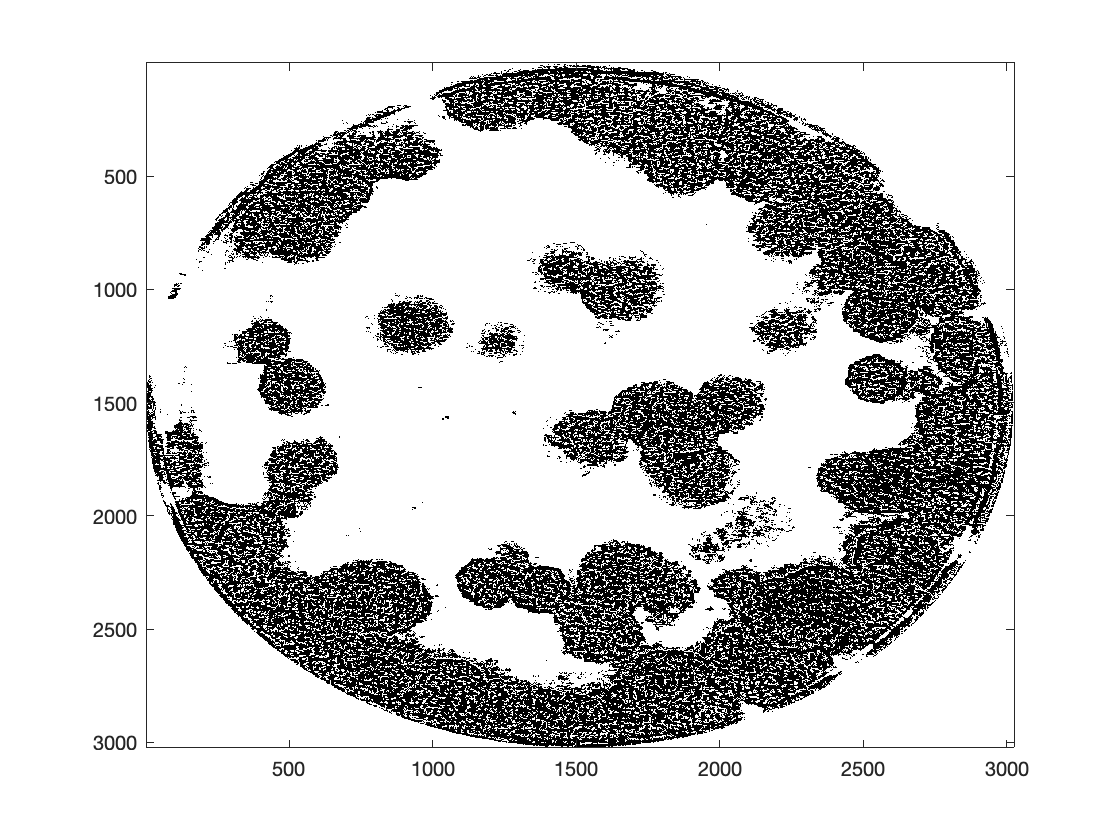

cd (filePath1);
    imgTitle = string(filenames(3));
    [analysisStats,C] = clonogenicAssay(imgTitle, filePath2, tableName);

filenames

filenames = 10×1 cell array
    {'7860_Fluva1.25+VHLa.jpeg'        }
    {'7860_Fluva1.25+VHLb.jpeg'        }
    {'7860_Fluva1.25c.jpeg'            }
    {'7860_Fluva1.25d.jpeg'            }
    {'7860_Fluva2.5+VHLa.jpeg'         }
    {'7860_Fluva2.5+VHLb.jpeg'         }
    {'7860_Fluva2.5c.jpeg'             }
    {'7860_Fluva5+VHLa.jpeg'           }
    {'7860_Fluva5+VHLb.jpeg'           }
    {'MONTAGE 7860_Fluva1.25+VHLa.jpeg'}


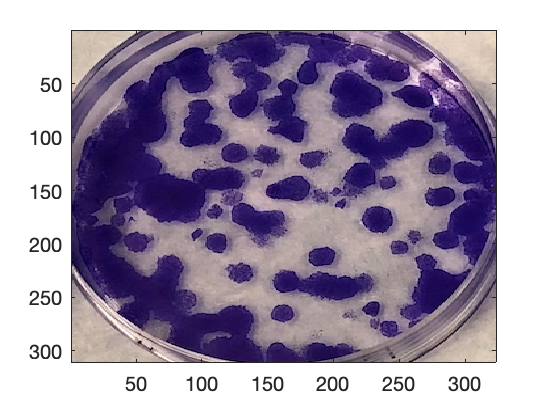

I = imread("7860_Fluva1.25+VHLa.jpeg");
imagesc(I)

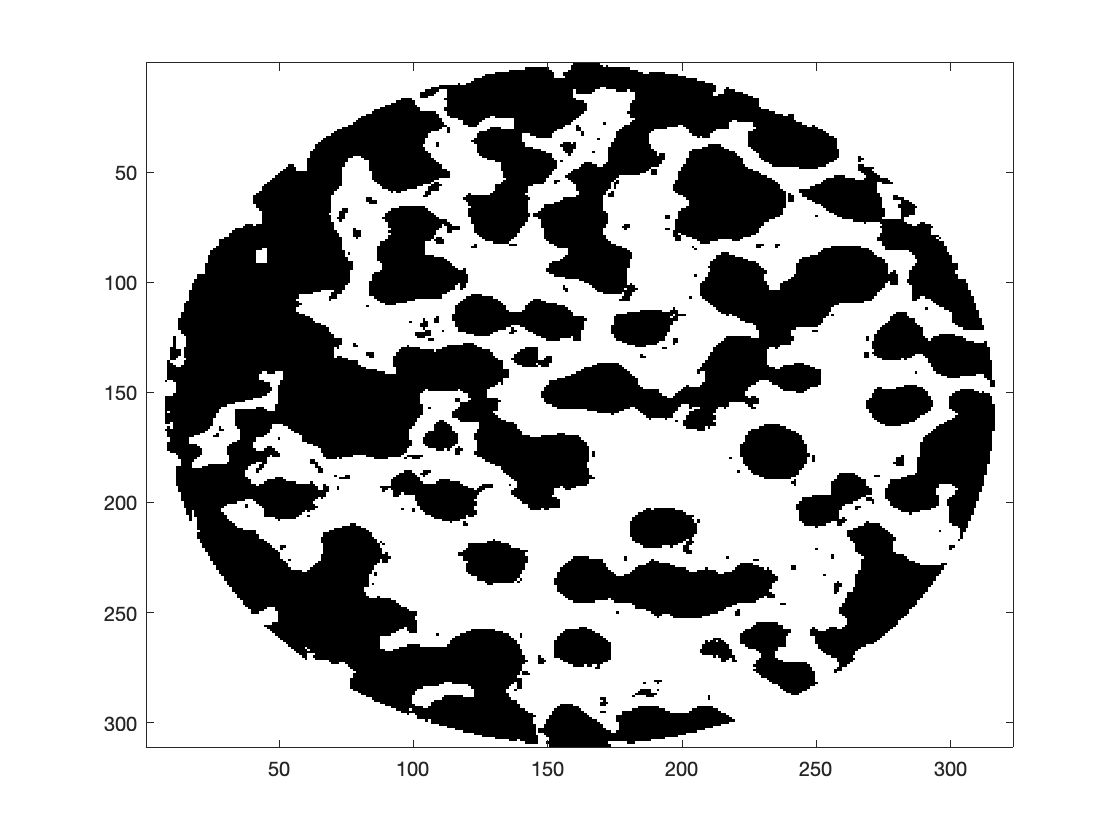

analysisStats = 36×2 table
             PhotoName              colonies
    ____________________________    ________

    "7860_Atorva_1.25+VHLa.jpeg"      147   
    "7860_Atorva_1.25+VHLb.jpeg"      131   
    "7860_Atorva_1.25c.jpeg"          127   
    "7860_Atorva_1.25d.jpeg"          149   
    "7860_Atorva_10+VHLa.jpeg"         72   
    "7860_Atorva_10+VHLb.jpeg"         78   
    "7860_Atorva_10c.jpeg"             73   
    "7860_Atorva_10d.jpeg"             59   
    "7860_Atorva_2.5+VHLa.jpeg"       128   
    "7860_Atorva_2.5+VHLb.jpeg"       123   
    "7860_Atorva_2.5c.jpeg"           122   
    "7860_Atorva_2.5d.jpeg"           110   
    "7860_Atorva_5+VHLa.jpeg"         140   
    "7860_Atorva_5+VHLb.jpeg"         128   
    "7860_Atorva_5c.jpeg"             114   
    "7860_Atorva_5d.jpeg"              50   


C = 311×646 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

[analysisStats,C] = clonogenicAssay("7860_Fluva1.25+VHLa.jpeg", filePath2, tableName);

analysisStats

analysisStats = 36×2 table
             PhotoName              colonies
    ____________________________    ________

    "7860_Atorva_1.25+VHLa.jpeg"      147   
    "7860_Atorva_1.25+VHLb.jpeg"      131   
    "7860_Atorva_1.25c.jpeg"          127   
    "7860_Atorva_1.25d.jpeg"          149   
    "7860_Atorva_10+VHLa.jpeg"         72   
    "7860_Atorva_10+VHLb.jpeg"         78   
    "7860_Atorva_10c.jpeg"             73   
    "7860_Atorva_10d.jpeg"             59   
    "7860_Atorva_2.5+VHLa.jpeg"       128   
    "7860_Atorva_2.5+VHLb.jpeg"       123   
    "7860_Atorva_2.5c.jpeg"           122   
    "7860_Atorva_2.5d.jpeg"           110   
    "7860_Atorva_5+VHLa.jpeg"         140   
    "7860_Atorva_5+VHLb.jpeg"         128   
    "7860_Atorva_5c.jpeg"             114   
    "7860_Atorva_5d.jpeg"              50   


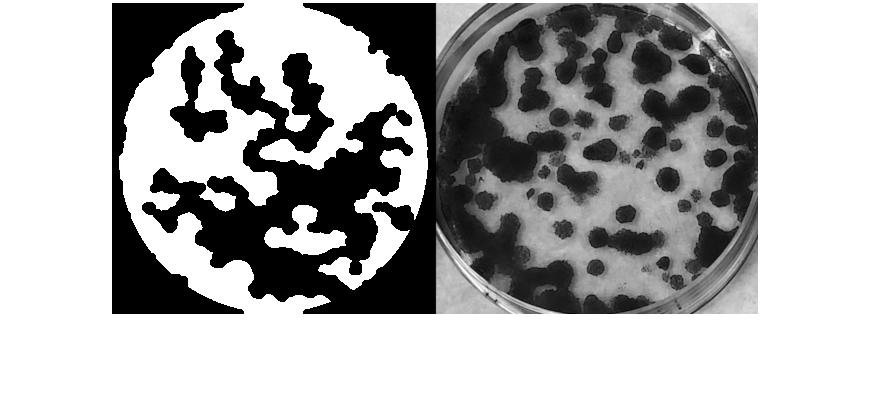

imshow(C)